%% ПОЛНЫЙ СКРИПТ: Объединение → Сохранение → Визуализация с номерами

clear all; close all; clc;

% ========== ПЕРЕМЕННЫЕ ДЛЯ НАСТРОЙКИ ==========
dir_name = "22";
numbering_type = "every_nth";  % "all", "every_nth", "global", "none"
point_step = 5;                % Показывать каждую N-ую точку
font_size = 9;                 % Размер шрифта номеров
% ==============================================

fprintf('═══════════════════════════════════════════════════════════\n');

═══════════════════════════════════════════════════════════


fprintf('ПОЛНЫЙ ПРОЦЕСС: Объединение → Сохранение → Визуализация\n');

ПОЛНЫЙ ПРОЦЕСС: Объединение → Сохранение → Визуализация


fprintf('═══════════════════════════════════════════════════════════\n\n');

═══════════════════════════════════════════════════════════




% ЭТАП 1: ОБЪЕДИНЕНИЕ ДАННЫХ
fprintf('ЭТАП 1: Объединение CSV файлов\n');

ЭТАП 1: Объединение CSV файлов


fprintf('───────────────────────────────────────────────────────────\n');

───────────────────────────────────────────────────────────



folder_path = fullfile('test_images', dir_name);
file_pattern = fullfile(folder_path, 'line_*_points.csv');
files = dir(file_pattern);

if isempty(files)
    error('Файлы не найдены в папке: %s', folder_path);
end

fprintf('Найдено файлов: %d\n\n', length(files));

Найдено файлов: 15




all_data = table();
file_summary = table();

for i = 1:length(files)
    try
        filepath = fullfile(folder_path, files(i).name);
        data = readtable(filepath);
        
        x = data.x;
        y = data.y;
        line_id = data.line_id(1);
        num_points = height(data);
        
        current_line_data = table(...
            repmat(line_id, num_points, 1), x, y, ...
            'VariableNames', {'line_id', 'x', 'y'});
        
        all_data = [all_data; current_line_data];
        file_summary = [file_summary; table(line_id, num_points, ...
            'VariableNames', {'line_id', 'points'})];
        
        fprintf('✓ Линия %2d (%3d точек)\n', line_id, num_points);
        
    catch ME
        fprintf('✗ Ошибка: %s\n', ME.message);
    end
end

✓ Линия  0 ( 27 точек)
✓ Линия 10 ( 51 точек)
✓ Линия 11 ( 35 точек)
✓ Линия 12 ( 40 точек)
✓ Линия 13 ( 35 точек)
✓ Линия 14 ( 26 точек)
✓ Линия  1 ( 33 точек)
✓ Линия  2 ( 41 точек)
✓ Линия  3 (  7 точек)
✓ Линия  4 ( 86 точек)
✓ Линия  5 ( 53 точек)
✓ Линия  6 ( 53 точек)
✓ Линия  7 ( 53 точек)
✓ Линия  8 ( 53 точек)
✓ Линия  9 ( 51 точек)



fprintf('\nВсего загружено: %d строк\n\n', height(all_data));


Всего загружено: 644 строк




% ЭТАП 2: СОХРАНЕНИЕ ДАННЫХ
fprintf('ЭТАП 2: Сохранение данных\n');

ЭТАП 2: Сохранение данных


fprintf('───────────────────────────────────────────────────────────\n');

───────────────────────────────────────────────────────────



% Создаём папку dir_name
save_folder = fullfile(pwd, dir_name);
if ~isfolder(save_folder)
    mkdir(save_folder);
    fprintf('✓ Папка создана: %s\n', dir_name);
else
    fprintf('✓ Папка существует: %s\n', dir_name);
end

✓ Папка существует: 22



% Сохраняем основной файл
data_filename = sprintf('combined_lines_%s.csv', dir_name);
data_filepath = fullfile(save_folder, data_filename);
writetable(all_data, data_filepath);
fprintf('✓ Сохранены данные: %s\n', data_filename);

✓ Сохранены данные: combined_lines_22.csv



% Сохраняем сводку
summary_filename = sprintf('lines_summary_%s.csv', dir_name);
summary_filepath = fullfile(save_folder, summary_filename);
writetable(file_summary, summary_filepath);
fprintf('✓ Сохранена сводка: %s\n\n', summary_filename);

✓ Сохранена сводка: lines_summary_22.csv




% ЭТАП 3: ВИЗУАЛИЗАЦИЯ
fprintf('ЭТАП 3: Построение графика\n');

ЭТАП 3: Построение графика


fprintf('───────────────────────────────────────────────────────────\n');

───────────────────────────────────────────────────────────


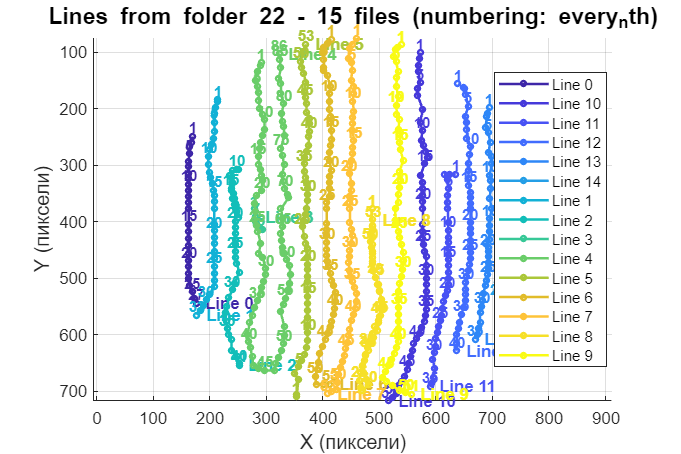


figure('Position', [100, 100, 1200, 800]);
hold on; 
grid on; 
axis equal;

colors = parula(max(length(files), 2));
global_point_number = 1;

for i = 1:length(files)
    try
        filepath = fullfile(folder_path, files(i).name);
        data = readtable(filepath);
        
        line_id = data.line_id(1);
        x = data.x;
        y = data.y;
        
        % Рисуем линию
        plot(x, y, 'o-', 'Color', colors(i,:), ...
            'LineWidth', 1.5, 'MarkerSize', 3, ...
            'DisplayName', sprintf('Line %d', line_id));
        
        % ========== ДОБАВЛЯЕМ НОМЕР К КАЖДОЙ ТОЧКЕ ==========
        
        if strcmp(numbering_type, "all")
            for point_idx = 1:length(x)
                text(x(point_idx), y(point_idx), ...
                    sprintf('%d', point_idx), ...
                    'FontSize', font_size, 'FontWeight', 'bold', ...
                    'Color', colors(i,:), ...
                    'HorizontalAlignment', 'center', ...
                    'VerticalAlignment', 'bottom', ...
                    'Margin', 1);
                global_point_number = global_point_number + 1;
            end
            
        elseif strcmp(numbering_type, "every_nth")
            for point_idx = 1:length(x)
                if mod(point_idx, point_step) == 0 || point_idx == length(x) || point_idx == 1
                    text(x(point_idx), y(point_idx), ...
                        sprintf('%d', point_idx), ...
                        'FontSize', font_size, 'FontWeight', 'bold', ...
                        'Color', colors(i,:), ...
                        'HorizontalAlignment', 'center', ...
                        'VerticalAlignment', 'bottom', ...
                        'Margin', 1);
                end
                global_point_number = global_point_number + 1;
            end
            
        elseif strcmp(numbering_type, "global")
            for point_idx = 1:length(x)
                if mod(point_idx, point_step) == 0 || point_idx == length(x) || point_idx == 1
                    text(x(point_idx), y(point_idx), ...
                        sprintf('%d', global_point_number), ...
                        'FontSize', font_size, 'FontWeight', 'bold', ...
                        'Color', colors(i,:), ...
                        'HorizontalAlignment', 'center', ...
                        'VerticalAlignment', 'bottom', ...
                        'Margin', 1);
                end
                global_point_number = global_point_number + 1;
            end
        else
            global_point_number = global_point_number + length(x);
        end
        
        % Подпись линии в конце
        last_x = x(end);
        last_y = y(end);
        text(last_x, last_y, sprintf('  Line %d', line_id), ...
            'FontSize', 10, 'FontWeight', 'bold', ...
            'Color', colors(i,:), ...
            'VerticalAlignment', 'middle', ...
            'HorizontalAlignment', 'left');
        
    catch ME
        fprintf('✗ Ошибка: %s\n', ME.message);
    end
end

xlabel('X (пиксели)', 'FontSize', 12); 
ylabel('Y (пиксели)', 'FontSize', 12);
title(sprintf('Lines from folder %s - %d files (numbering: %s)', ...
    dir_name, length(files), numbering_type), ...
    'FontSize', 14, 'FontWeight', 'bold');
legend('Location', 'best', 'FontSize', 9);
set(gca, 'YDir', 'reverse');

hold off;


% ИТОГОВАЯ ИНФОРМАЦИЯ
fprintf('\n───────────────────────────────────────────────────────────\n');


───────────────────────────────────────────────────────────


fprintf('ИТОГО:\n');

ИТОГО:


fprintf('───────────────────────────────────────────────────────────\n\n');

───────────────────────────────────────────────────────────




fprintf('📁 Папка для сохранения: %s/\n', dir_name);

📁 Папка для сохранения: 22/


fprintf('📄 Основной файл:       %s\n', data_filename);

📄 Основной файл:       combined_lines_22.csv


fprintf('📊 Файл сводки:         %s\n', summary_filename);

📊 Файл сводки:         lines_summary_22.csv


fprintf('📈 Тип нумерации:       %s\n', numbering_type);

📈 Тип нумерации:       every_nth


fprintf('📍 Загружено точек:     %d\n', global_point_number - 1);

📍 Загружено точек:     644



fprintf('\n═══════════════════════════════════════════════════════════\n');


═══════════════════════════════════════════════════════════


fprintf('✓ ЗАВЕРШЕНО!\n');

✓ ЗАВЕРШЕНО!


fprintf('═══════════════════════════════════════════════════════════\n');

═══════════════════════════════════════════════════════════
